## **Problem 13:**

**Here is a problem whose solution may be useful to you in the future. On the Internet you will find information suggesting that an inverse DFT can be computed using a forward DFT software routine in the process shown in Figure P3-13.**

**(A)**

**DFT:   **$X\left(k\right)=\sum_{n=0}^{N-1} {x_n e}^{\frac{-\mathrm{j2}\pi }{N}\mathrm{kn}}$

            
$$x\left(\omega \right)=\sum_{n=-\infty }^{\infty } x\left(n\right)\;e^{-j\omega n}$$


**IDFT: **$X\left(n\right)=\frac{1}{N}\sum_{m=0}^{N-1} {X\left(m\right)e}^{\frac{j\left(2\pi \mathrm{nm}\right)}{N}}$

           
$$x\left(n\right)=\frac{1}{N}\;\sum_{k\;=\;0}^{N-1} x\left(k\right)e^{\frac{\left(\mathrm{j2}\pi \mathrm{nk}\right)}{N}} \;$$


Complex Conjugate:


$$x\left(n\right)\longleftrightarrow x\left(-k*\mathrm{mod}\;N\right)$$



$$x\left(-n*\mathrm{mod}\;N\right)\longleftrightarrow x\left(k\right)$$


Proven through:

 
$$x\left(k\right)=x\left(-k*\mathrm{mod}\;N\right)$$



$$X\left(k\right)=\sum_{n=0}^{N-1} {x\left(n\right)e}^{\frac{-\mathrm{j2}\pi }{N}\left(-k\;\mathrm{modN}\right)n}$$


         
$$=\sum_{n=0}^{N-1} {x\left(n\right)e}^{\frac{-\mathrm{j2}\pi }{N}\left(\mathrm{kn}\right)}$$



$$X\left(-k\;\mathrm{mod}\;N\right)=X\left(k\right)$$


**(B)**

## **Problem 14:**

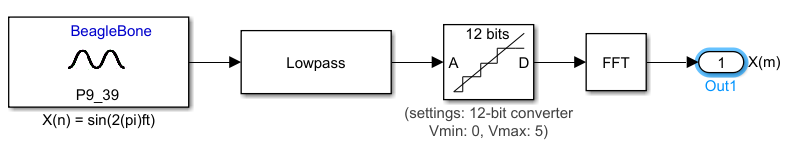

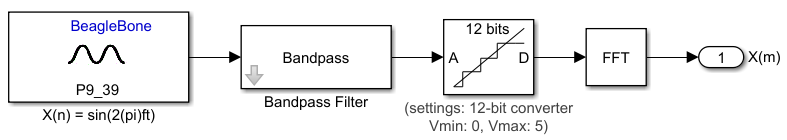

We can use sampling methods shown in chapter 2, such as lowpass filtering and Bandpass filtering.

## **Problem 15:**

**Unable to comprehend correctly, would appreciate example done in class**

## **Problem 16:**

clf
n = 1:47

n =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47


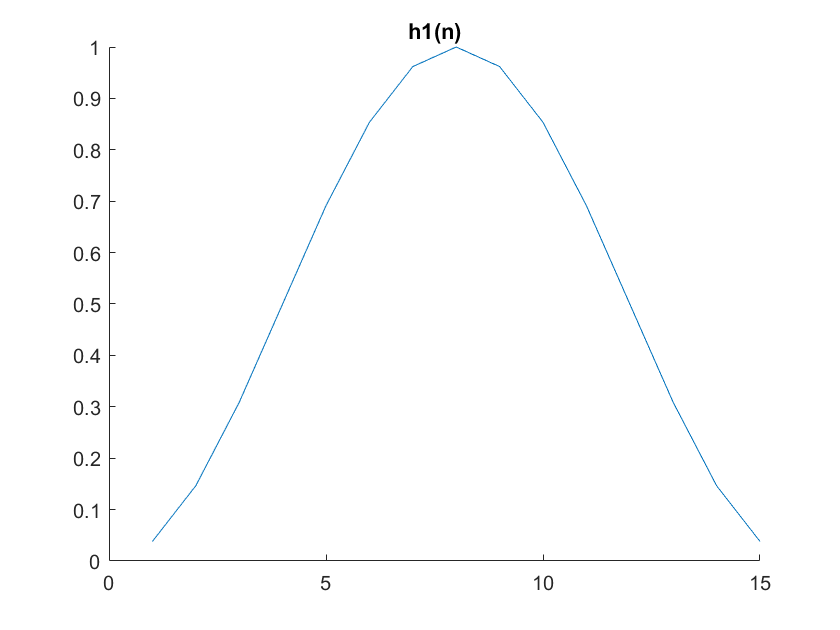

figure
for n = 1 : 15
    h1(n) = 0.5-.5*(cos((2*pi*n)/16));
    hold on
    plot(h1)
end
title("h1(n)")
hold off

**(A) **$h_1 \left(n\right)$ is made of two signals, a DC signal of 0.5, and a signal $-0\ldotp 5\;\mathrm{cos}\left(\frac{2\pi n}{16}\right)$. $h_1 \left(n\right)$ looks the way it does, because it has a positive component of 0.5 meaning the y value is offset by 0.5, and there is a frequency over time that is shifting up and down from 0 to 1 by subtracting the resultant of the signal.

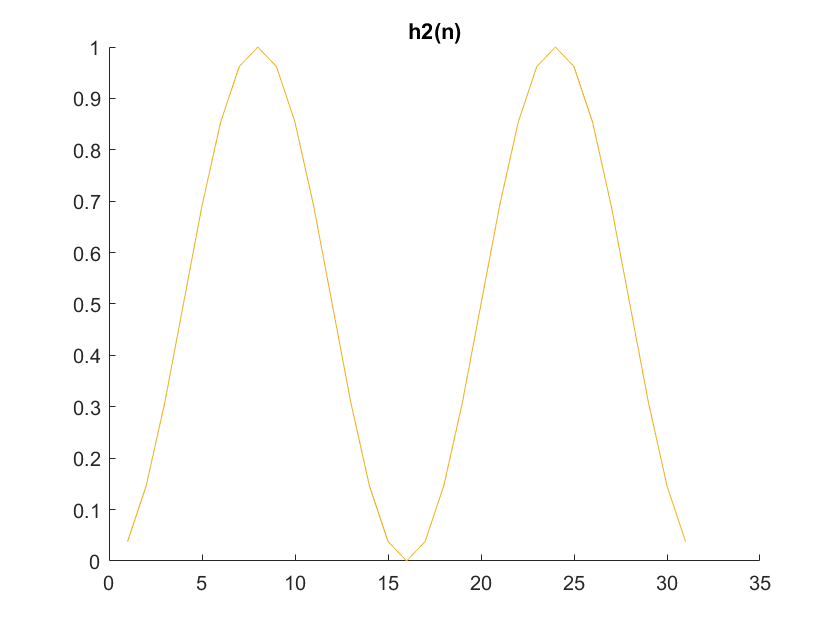

clf
figure
for n = 1 : 31
    h2(n) = .5 -.5*(cos((2*pi*n)/16));
    hold on
    plot(h2)
end
title("h2(n)")
hold off

**(B)**

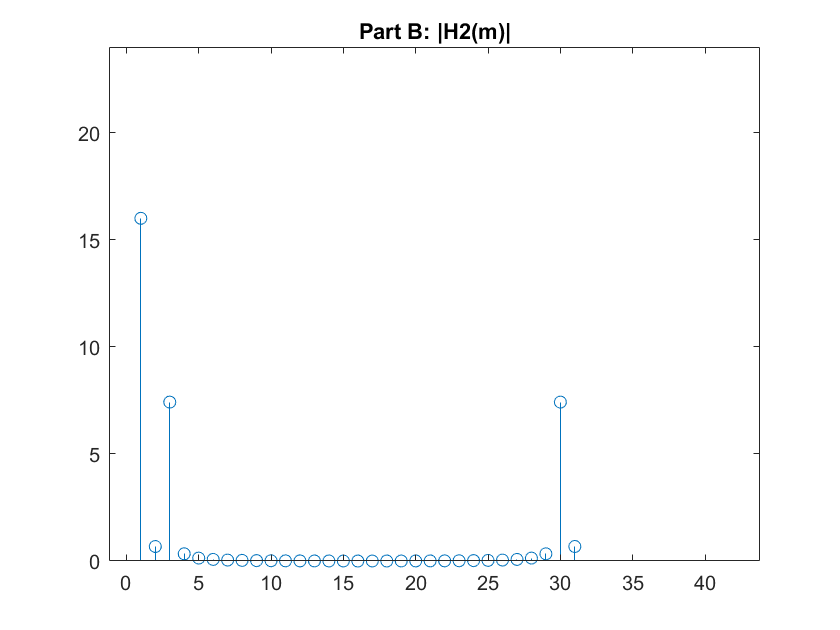

figure
f=abs(real(fft(h2)));
stem(1:31,f)
xlim([-1.2 43.8])
ylim([0.0 24.0])
title("Part B: |H2(m)|")

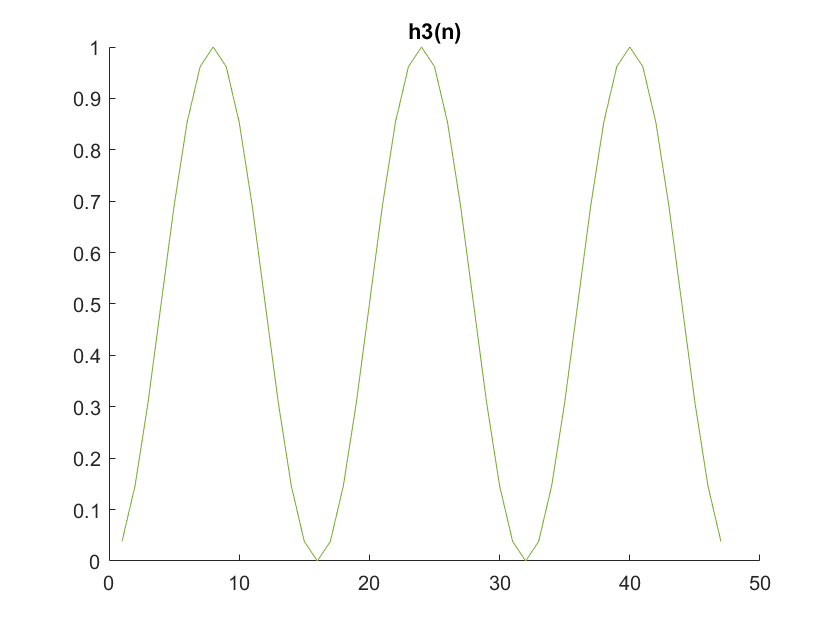

clf
figure
for n = 1 : 47
    h3(n) = .5 -.5*(cos((2*pi*n)/16));
    hold on
    plot(h3)
end
title("h3(n)")
hold off

**(C)**

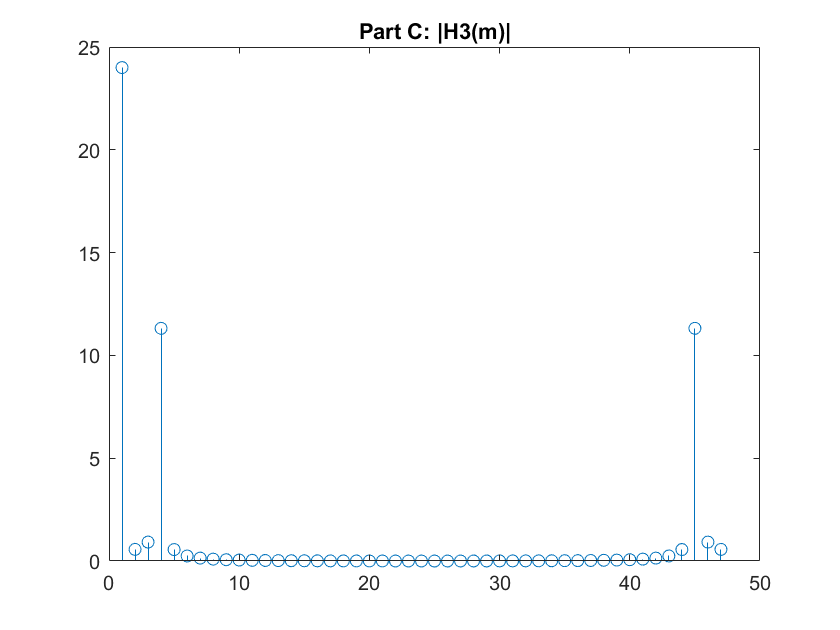

figure
f=abs(real(fft(h3)));
stem(1:47,f)
title("Part C: |H3(m)|")

**(D)**

**“K repetitions of an h1(n) sequence result in an extended-length time sequence whose spectral magnitudes have K−1 ...”**

**            GAIN**

## **Problem 18:**

A Continuous fourier transform is performed in which there are a number of padded zeros in the data. The transform creates a centered wave form, where as Q increases the observer will see graphical points that resemble the wave itself.

## **Problem 20:**

SNR_N = 10*log(1000000/100)

SNR_N = 92.1034

Gain of 92.103 in their signal